## Analysis of quartet FVN series

-rw-r--r--  1 kawahara  staff   2479916  2 14 00:17 minPeakMixFvnSequence.wav

-rw-r--r--@ 1 kawahara  staff  10590776  2 14 00:22 minPeakMixFvnSequenceRec1.wav

-rw-r--r--@ 1 kawahara  staff  17720876  2 25 02:17 mixQuartetFVN80rep.wav

-rw-r--r--@ 1 kawahara  staff  35441708  2 25 02:17 mixQuartetFVN80repStereo.wav

-rw-r--r--@ 1 kawahara  staff  38263352  2 25 02:27 mixQuartetFVN80repRec2Ch.wav

-rw-r--r--@ 1 kawahara  staff  37722680  2 25 02:30 mixQuartetFVN80repRecLCh.wav

-rw-r--r--@ 1 kawahara  staff  37280312  2 25 02:33 mixQuartetFVN80repRecRCh.wav

-rw-r--r--@ 1 kawahara  staff  36911672  2 25 02:37 mixQuartetFVN80repStereoRec.wav

-rw-r--r--@ 1 kawahara  staff  38287928  2 25 02:40 silenceRec.wav

close all
clear variables


nSequence = 4;
fvnIds = [10, 6, 14, 2];
tResponse = 0.2;
unitRepetition = 8;
fs = 44100;
load fvnMin200ms.mat
outputRef = fvn2orthogonalSequence(fvnMin200ms, nSequence, fvnIds, fs, tResponse, unitRepetition)

outputRef = フィールドをもつ struct :
    fvnOrthogonalSequence: [826624×4 double]
         fvnMixedSequence: [826624×1 double]
        cOrthogonalBinary: [64×4 double]
                   fvnIds: [10 6 14 2]
             maxPeakValue: 0.0813
                lResponse: 8820
            kurtosisValue: 2.9759
              nRepetition: 64
           unitRepetition: 8
                 usedFvns: [262144×4 double]


### Fetch a measured data file

load fvnMin200ms.mat
nBaseUnit = 8;
fName = "mixQuartetFVN80repRecLCh.wav";
%fName = "mixQuartetFVN80repRec.wav";
[x, fs] = audioread(fName);
nData = length(x);
bufferL = zeros(nData, nSequence);
bufferR = zeros(nData, nSequence);
basIdx = 1:nData;
fvnSet = fvnMin200ms;

### Pulse compression and decorrelation

Note, that at this stage, fair amount of crosscorrelation remains.

cOrthCoeff = outputRef.cOrthogonalBinary;
for ii = 1:nSequence
    tmp = fftfilt(fvnSet(end:-1:1, fvnIds(ii)), x);
    bufferL(:, ii) = tmp(:, 1);
    bufferR(:, ii) = tmp(:, 2);
end


Let's visualize it for the first sequence

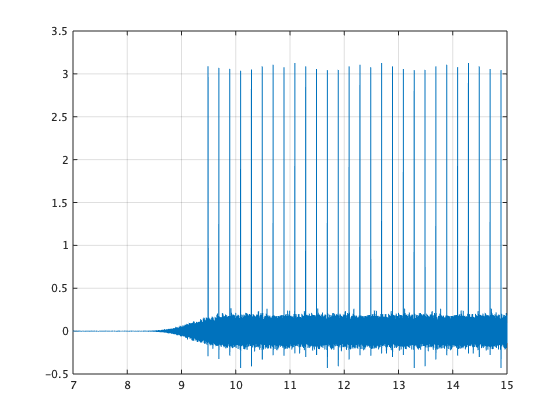

tx = (1:nData)' / fs;
figure;
plot(tx, bufferR(:, 1));
grid on
set(gca, 'XLim', [7 15]);

nSkip = outputRef.lResponse;
orthogonalBufferL = bufferL * 0;
orthogonalBufferR = bufferR * 0;
for jj = 1:nSequence
    for ii = 1:nBaseUnit
        tmpIdx = min(nData ,basIdx + (ii - 1) * nSkip);
        orthogonalBufferL(:, jj) = orthogonalBufferL(:, jj) ...
            + bufferL(tmpIdx, jj) * cOrthCoeff(ii, jj);
        orthogonalBufferR(:, jj) = orthogonalBufferR(:, jj) ...
            + bufferR(tmpIdx, jj) * cOrthCoeff(ii, jj);
    end
end


### visualize the results

Note, crosscorrelation effects are (virtually) completely removed.

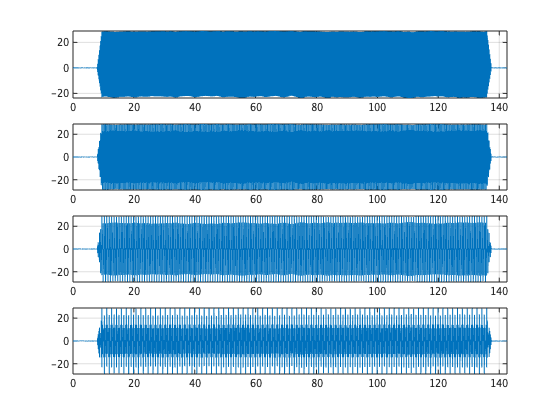

tx = (1:nData)' / fs;
figure;
subplot(411)
plot(tx, orthogonalBufferL(:, 1)); grid on;
set(gca, 'XLim', [0 tx(end)]);
subplot(412)
plot(tx, orthogonalBufferL(:, 2)); grid on;
set(gca, 'XLim', [0 tx(end)]);
subplot(413)
plot(tx, orthogonalBufferL(:, 3)); grid on;
set(gca, 'XLim', [0 tx(end)]);
subplot(414)
plot(tx, orthogonalBufferL(:, 4)); grid on;
set(gca, 'XLim', [0 tx(end)]);

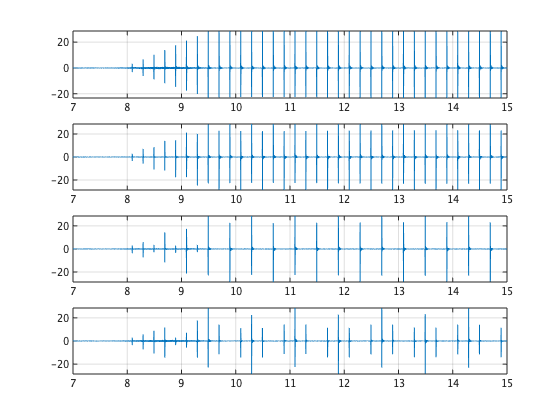


figure;
subplot(411)
plot(tx, orthogonalBufferL(:, 1)); grid on;
set(gca, 'XLim', [7 15]);
subplot(412)
plot(tx, orthogonalBufferL(:, 2)); grid on;
set(gca, 'XLim', [7 15]);
subplot(413)
plot(tx, orthogonalBufferL(:, 3)); grid on;
set(gca, 'XLim', [7 15]);
subplot(414)
plot(tx, orthogonalBufferL(:, 4)); grid on;
set(gca, 'XLim', [7 15]);

### Check the reference signal to determine the proper time origin to start analysys

The plots suggests that the peak just after 11s is the best origin.

figure;
subplot(211)
plot(tx, sum(orthogonalBufferR, 2)); grid on;
set(gca, 'XLim', [7 15]);
subplot(212)
plot(tx, 20*log10(abs(sum(orthogonalBufferR, 2))));
grid on;
axis([7 15 -50 50])


Then, find the index of the second one

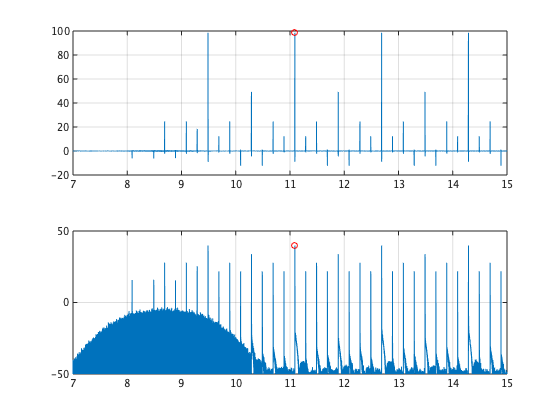

refSignal = sum(orthogonalBufferR, 2);
maxPeak = max(refSignal);
originCandidates = basIdx(tx < 15 & refSignal > 0.95 * maxPeak);
originIdx = originCandidates(2);
subplot(211)
hold on
plot(originIdx / fs, refSignal(originIdx), 'ro');
subplot(212)
hold on
plot(originIdx / fs, 20*log10(abs(refSignal(originIdx))), 'ro');

### Simple synchronized averaging using orthogonal binary sequence

preMargin = 100;
unitBufferL = zeros(nBaseUnit * nSkip + preMargin, nSequence);
unitBufferR = zeros(nBaseUnit * nSkip + preMargin, nSequence);
nAveraging = floor((120 - originIdx / fs) / (nBaseUnit * nSkip / fs)) * nBaseUnit;
unitIdx = 1:nBaseUnit * nSkip + preMargin;
for ii = 1:nAveraging
    currentIdx = unitIdx + (ii - 1) * nSkip - preMargin + originIdx;
    for jj = 1:nSequence
        tmpCoeff = cOrthCoeff(rem(ii - 1, nBaseUnit) + 1, jj);
        unitBufferL(:, jj) = unitBufferL(:, jj) ...
            + bufferL(currentIdx, jj) * tmpCoeff;
        unitBufferR(:, jj) = unitBufferR(:, jj) ...
            + bufferR(currentIdx, jj) * tmpCoeff;
    end
end

### Display the indifidual impulse response and extended response

This section shows the individual responses

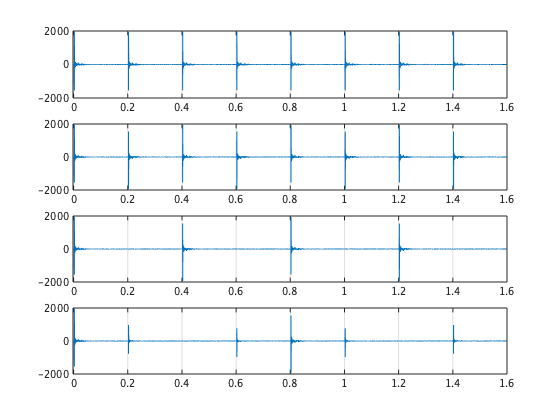

unitTx = (unitIdx - preMargin) / fs;
figure;
subplot(411)
plot(unitTx, unitBufferL(:, 1));
grid on;
set(gca, 'XLim', [unitTx(1) unitTx(end)]);
subplot(412)
plot(unitTx, unitBufferL(:, 2));
grid on;
set(gca, 'XLim', [unitTx(1) unitTx(end)]);
subplot(413)
plot(unitTx, unitBufferL(:, 3));
grid on;
set(gca, 'XLim', [unitTx(1) unitTx(end)]);
subplot(414)
plot(unitTx, unitBufferL(:, 4));
grid on;
set(gca, 'XLim', [unitTx(1) unitTx(end)]);

First, calculate the weight to extend the response length.


$$\mathrm{B}=\left\lbrack \begin{array}{cccc}
1 & 1 & 1 & 1\\
1 & -1 & 0 & \frac{1}{2}\\
1 & 1 & -1 & 0\\
1 & -1 & 0 & \frac{1}{2}
\end{array}\right\rbrack$$


$\left\lbrack \begin{array}{c}
1\\
0\\
0\\
0
\end{array}\right\rbrack =\mathrm{B}\;\mathit{\mathbf{r}}$, $\mathit{\mathbf{r}}$  = ${\mathrm{B}}^{-1}$$\left\lbrack \begin{array}{c}
1\\
0\\
0\\
0
\end{array}\right\rbrack$ , $\mathit{\mathbf{r}}=\frac{1}{4}\left\lbrack \begin{array}{c}
1\\
1\\
2\\
0
\end{array}\right\rbrack$

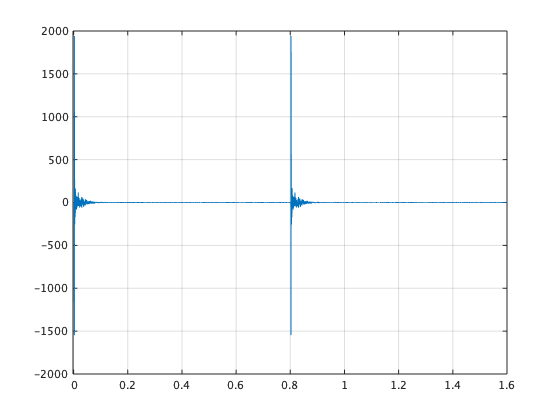


extendedResponse = (unitBufferL(:, 1) + unitBufferL(:, 2) + unitBufferL(:, 3) * 2) / 4;
figure
plot(unitTx, extendedResponse); grid on;
grid on;
set(gca, 'XLim', [unitTx(1) unitTx(end)]);

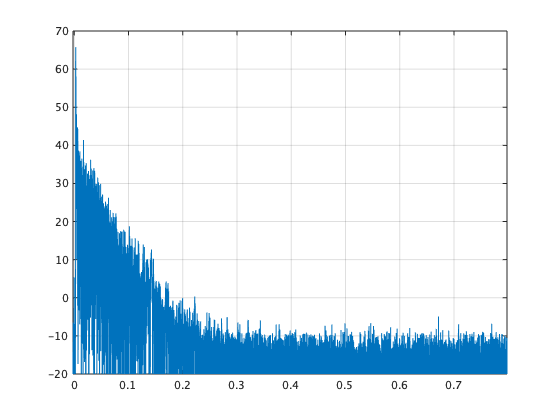


figure
plot(unitTx, 20 * log10(abs(extendedResponse))); grid on;
grid on;
axis([unitTx(1) unitTx(1) + 0.8 -20 70])

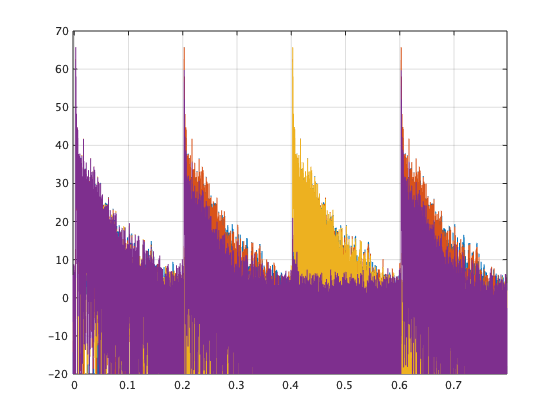


initialIdx = unitIdx - preMargin + originIdx;
figure;
plot(unitTx, 20*log10(abs(nAveraging * orthogonalBufferL(initialIdx, :) / nBaseUnit)));
grid on;
axis([unitTx(1) unitTx(1) + 0.8 -20 70])

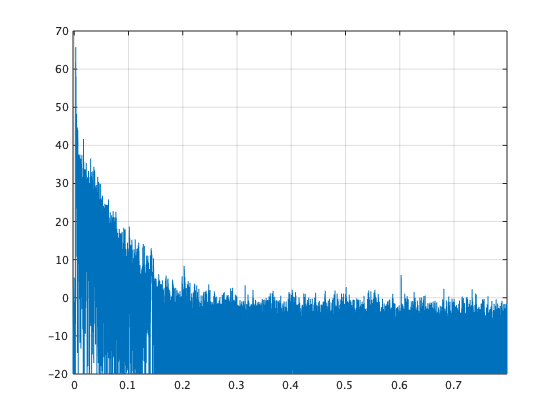


extendedResponseOneShot = ...
    (orthogonalBufferL(:, 1) + orthogonalBufferL(:, 2) ...
    + orthogonalBufferL(:, 3) * 2) / 4;
figure;
plot(unitTx, 20*log10(abs(nAveraging * extendedResponseOneShot(initialIdx) / nBaseUnit)));
grid on;
axis([unitTx(1) unitTx(1) + 0.8 -20 70])

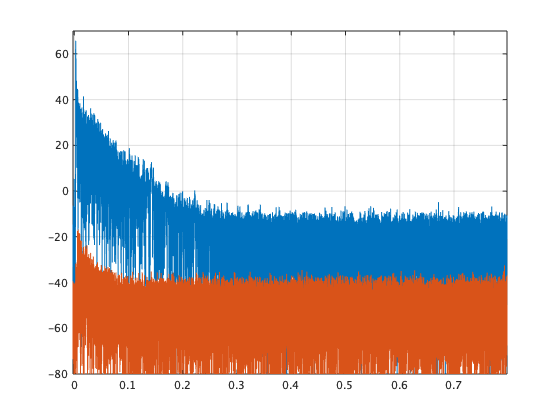


halfIdx = (1:nBaseUnit * nSkip / 2);
figure
plot(unitTx(halfIdx), 20 * log10(abs(extendedResponse(halfIdx) ...
    + extendedResponse(halfIdx + nBaseUnit * nSkip / 2)) / 2)); grid on;
hold all
plot(unitTx(halfIdx), 20 * log10(abs(extendedResponse(halfIdx) ...
    - extendedResponse(halfIdx + nBaseUnit * nSkip / 2)) / 2)); grid on;
grid on;
axis([unitTx(1) unitTx(1) + 0.8 -80 70])

### First test of background noise level

This section was a bad idea

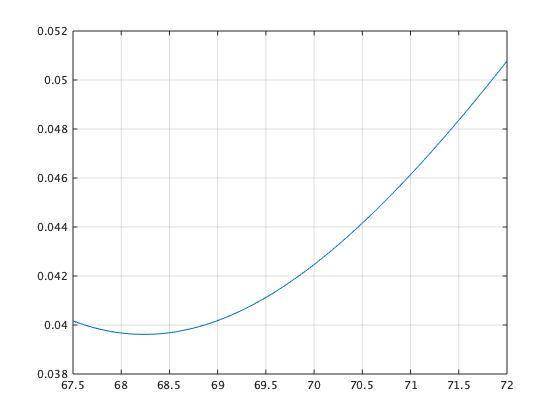

corrctorList = 67.5:0.01:72;
stdList = zeros(length(corrctorList), 1);
for ii = 1:length(corrctorList)
    stdList(ii) = std(orthogonalBufferL(initialIdx, 1) ...
        - unitBufferL(:, 1)/corrctorList(ii));
end
figure;
plot(corrctorList, stdList);
grid on;

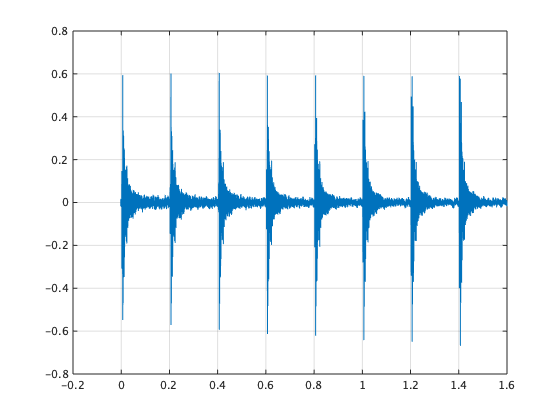

[~, minIdx] = min(stdList);
corrector = corrctorList(minIdx);
figure;
plot(unitTx, orthogonalBufferL(initialIdx, 1) ...
    - unitBufferL(:, 1)/corrector);
grid on

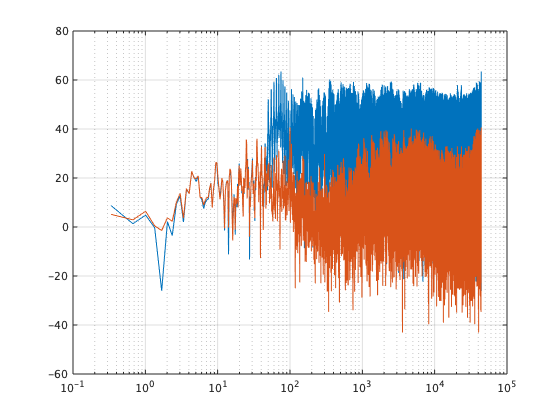


figure;
fftlUnitResp = 2 ^ ceil(log2(length(unitTx)));
fxUnitResp = (0:fftlUnitResp - 1) / fftlUnitResp * fs;
semilogx(fxUnitResp, ...
    20 * log10(abs(fft(orthogonalBufferL(initialIdx, 1), fftlUnitResp))));
grid on
diffSignal = orthogonalBufferL(initialIdx, 1) ...
    - unitBufferL(:, 1)/corrector;
hold all
semilogx(fxUnitResp, ...
    20 * log10(abs(fft(diffSignal, fftlUnitResp))));

### Compare response under the same condition

movement of  my body contribution matters. Direct sound part is highly reproducible

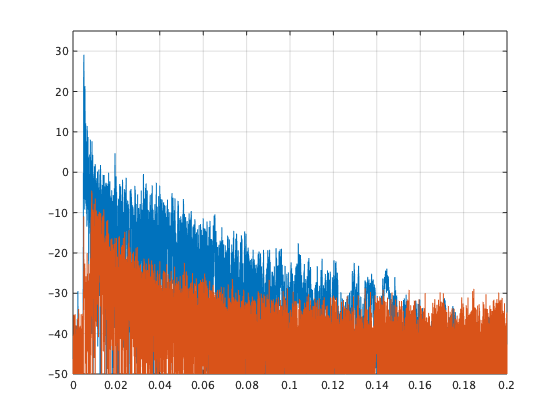

baseIdx = 1:nSkip;
initialIdx = baseIdx - preMargin + originIdx;
nUnitRepetition = (120 * fs - originIdx) / (nSkip * nBaseUnit);
baseResponseL = zeros(nSkip, 1);
for ii = 1:nUnitRepetition
    baseResponseL = baseResponseL ...
        + orthogonalBufferL(initialIdx + (ii - 1) * (nSkip * nBaseUnit), 1);
end
baseResponseL = baseResponseL / nUnitRepetition;
testResidual = baseResponseL - orthogonalBufferL(initialIdx, 1);
figure;
plot(baseIdx / fs, 20*log10(abs(baseResponseL)));grid on
hold all
plot(baseIdx / fs, 20*log10(abs(testResidual)));
set(gca, 'YLim', [ -50 35]);

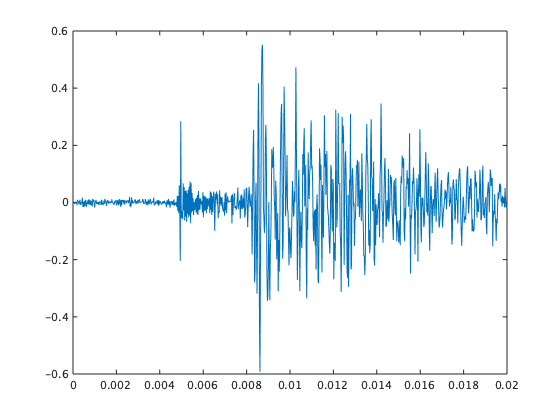


figure;
%plot(baseIdx / fs, baseResponseL);grid on
%hold all
plot(baseIdx / fs, testResidual);
set(gca, 'xLim', [0 0.02]);

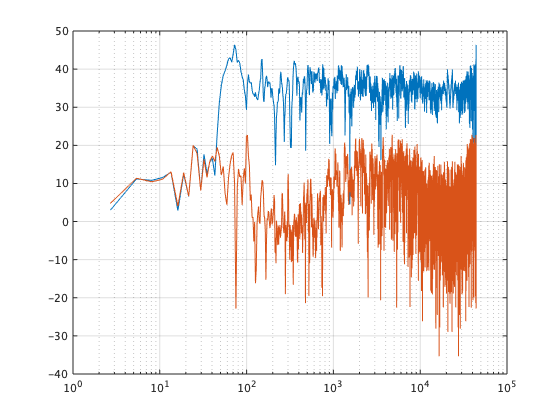


figure;
fftlUnitResp = 2 ^ ceil(log2(nSkip));
fxUnitResp = (0:fftlUnitResp - 1) / fftlUnitResp * fs;
semilogx(fxUnitResp, ...
    20 * log10(abs(fft(orthogonalBufferL(initialIdx, 1), fftlUnitResp))));
grid on
hold all
semilogx(fxUnitResp, ...
    20 * log10(abs(fft(testResidual, fftlUnitResp))));

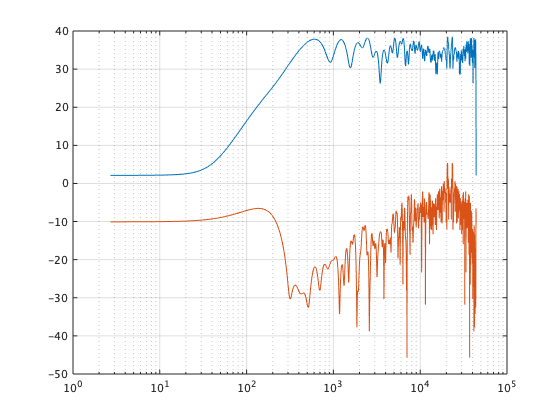


figure;
fftlUnitResp = 2 ^ ceil(log2(nSkip));
fxUnitResp = (0:fftlUnitResp - 1) / fftlUnitResp * fs;
semilogx(fxUnitResp, ...
    20 * log10(abs(fft(orthogonalBufferL(initialIdx(1:330), 1), fftlUnitResp))));
grid on
hold all
semilogx(fxUnitResp, ...
    20 * log10(abs(fft(testResidual(1:330), fftlUnitResp))));

### Check the difference in unit-by-unit

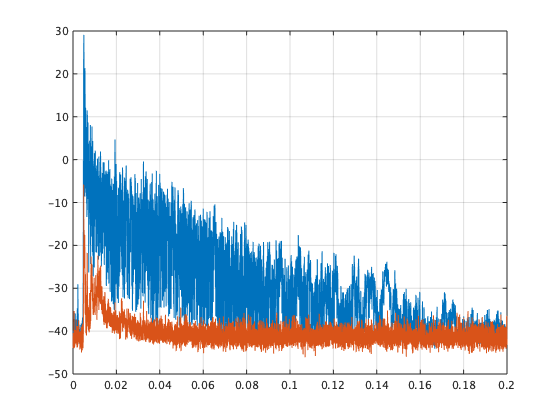

baseIdx = 1:nSkip;
initialIdx = baseIdx - preMargin + originIdx;
nUnitRepetition = (120 * fs - originIdx) / (nSkip * nBaseUnit);
rmsDifferenceL = zeros(nSkip, 1);
rmsLevelL = zeros(nSkip, 1);
txUnit = baseIdx / fs;
mainResponseSpec = zeros(fftlUnitResp, 1);
wholeDifferenceSpec = zeros(fftlUnitResp, 1);
backGroundSpec = zeros(fftlUnitResp, 1);
for ii = 2:nUnitRepetition
    currentResponse = ...
        orthogonalBufferL(initialIdx + (ii - 1) * (nSkip * nBaseUnit), 1);
    diffResponse = ...
        orthogonalBufferL(initialIdx + (ii - 1) * (nSkip * nBaseUnit), 1) ...
        - orthogonalBufferL(initialIdx + (ii - 2) * (nSkip * nBaseUnit), 1);
    rmsDifferenceL = rmsDifferenceL + diffResponse .^ 2;
    rmsLevelL = rmsLevelL + currentResponse .^ 2;
    mainResponseSpec = mainResponseSpec + abs(fft(currentResponse, fftlUnitResp)) .^ 2;
    wholeDifferenceSpec = wholeDifferenceSpec + abs(fft(diffResponse, fftlUnitResp)) .^ 2;
    backGroundSpec = backGroundSpec + ...
        abs(fft(diffResponse(txUnit > 0.06), fftlUnitResp)) .^ 2;
end
rmsLevelL = rmsLevelL / (nUnitRepetition - 1);
rmsDifferenceL = rmsDifferenceL / (nUnitRepetition - 1) / 2;
figure;
plot(baseIdx / fs, 10 * log10(rmsLevelL)); grid on
hold all
plot(baseIdx / fs, 10 * log10(rmsDifferenceL)); grid on

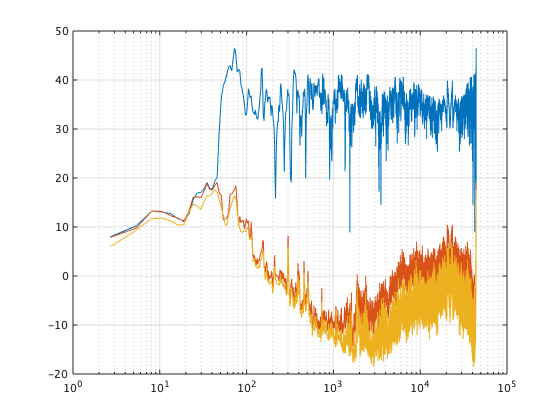


mainResponseSpec = mainResponseSpec / (nUnitRepetition - 1);
wholeDifferenceSpec = wholeDifferenceSpec / (nUnitRepetition - 1) / 2;
backGroundSpec = backGroundSpec / (nUnitRepetition - 1) / 2;
figure;
semilogx(fxUnitResp, 10 * log10(mainResponseSpec));
hold all
semilogx(fxUnitResp, 10 * log10(wholeDifferenceSpec));
semilogx(fxUnitResp, 10 * log10(backGroundSpec));
grid on

### Compare spectrum of the recording of silent period

Comparison between silent recording and difference between unit frames suggest the deviation higher than 1kHz region is due to temporal variation. In that reagion, the spetra are modified by +20dB/decade suggesting time derivative. This mismatch can be used for time axis alignment.

[xs, fss] = audioread("silenceRec.wav");
xsilence = xs(:, 1);
nData = length(xsilence);
sGramSilence = stftSpectrogramStructure(xsilence, fs, 400, 20, "nuttallwin");
sGramLch = stftSpectrogramStructure(x(:, 1), fs, 400, 20, "nuttallwin");

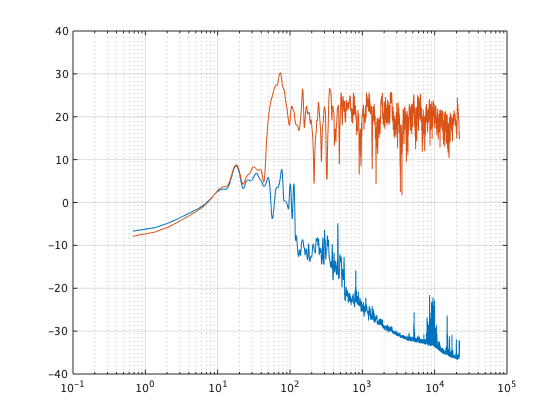


averageSilencePowerSpec = mean(sGramSilence.rawSpectrogram, 2);
recordedSignalPowerSpec = mean(sGramLch.rawSpectrogram, 2);
figure;semilogx(sGramSilence.frequencyAxis, 10*log10(averageSilencePowerSpec)); grid on;
hold all
semilogx(sGramLch.frequencyAxis, 10*log10(recordedSignalPowerSpec));

### Let's check what happens by adjusting time alignment

OK, this suggests, it is not such simple.

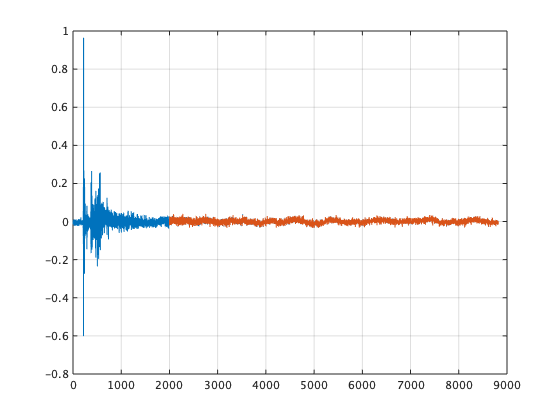


xseg1 = orthogonalBufferL(initialIdx + (1 - 1) * (nSkip * nBaseUnit), 1);
xseg2 = orthogonalBufferL(initialIdx + (2 - 1) * (nSkip * nBaseUnit), 1);
refIdx = (2000:length(xseg1))';
%refIdx = (2:2000)';
timeDeviation = -0.1:0.001:0.1;
pwr = zeros(length(timeDeviation), 1);
for ii = 1:length(timeDeviation)
    xseg2mod = interp1(refIdx, xseg2(refIdx), refIdx + timeDeviation(ii), 'linear', "extrap");
    pwr(ii) = std(diff(diff(xseg1(refIdx) - xseg2mod(:))));
end
[~, minIdx] = min(pwr);
xseg2mod = interp1(refIdx, xseg2(refIdx), refIdx + timeDeviation(minIdx), 'linear', "extrap");
figure;
plot(xseg2 - xseg1);
hold all
plot(refIdx, xseg2mod - xseg1(refIdx)); grid on;

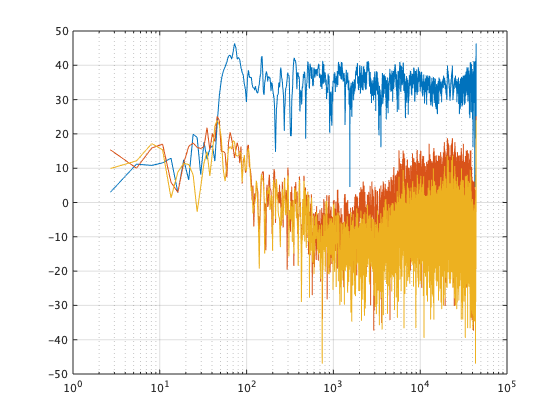


figure;
semilogx(fxUnitResp, 20 * log10(abs(fft(xseg1, fftlUnitResp))));
grid on;
hold all
semilogx(fxUnitResp, 20 * log10(abs(fft(xseg2 - xseg1, fftlUnitResp))));
semilogx(fxUnitResp, 20 * log10(abs(fft(xseg2mod - xseg1(refIdx), fftlUnitResp))));

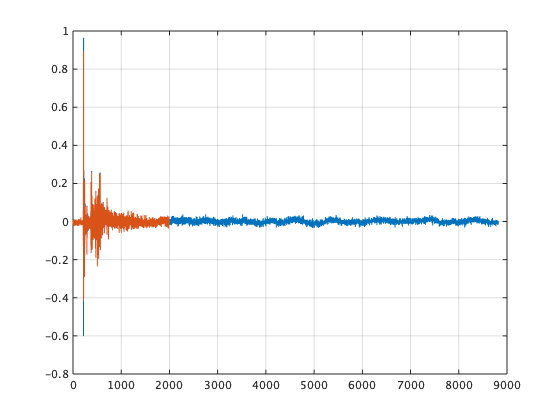


%refIdx = (2000:length(xseg1))';
refIdx = (2:2000)';
timeDeviation = -0.1:0.001:0.1;
pwr = zeros(length(timeDeviation), 1);
for ii = 1:length(timeDeviation)
    xseg2mod = interp1(refIdx, xseg2(refIdx), refIdx + timeDeviation(ii), 'linear', "extrap");
    pwr(ii) = std(diff(diff(xseg1(refIdx) - xseg2mod(:))));
end
[~, minIdx] = min(pwr);
xseg2mod = interp1(refIdx, xseg2(refIdx), refIdx + timeDeviation(minIdx), 'linear', "extrap");
figure;
plot(xseg2 - xseg1);
hold all
plot(refIdx, xseg2mod - xseg1(refIdx)); grid on;

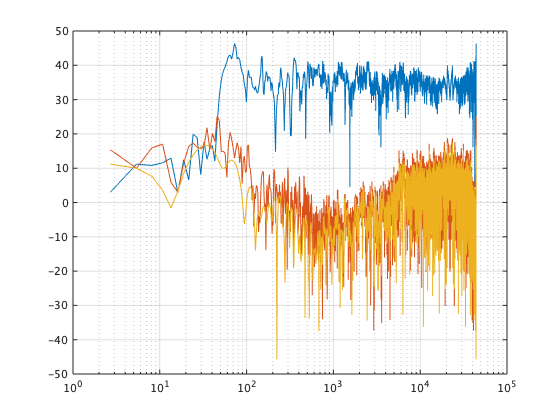


figure;
semilogx(fxUnitResp, 20 * log10(abs(fft(xseg1, fftlUnitResp))));
grid on;
hold all
semilogx(fxUnitResp, 20 * log10(abs(fft(xseg2 - xseg1, fftlUnitResp))));
semilogx(fxUnitResp, 20 * log10(abs(fft(xseg2mod - xseg1(refIdx), fftlUnitResp))));

### Return to classic, reverse integration

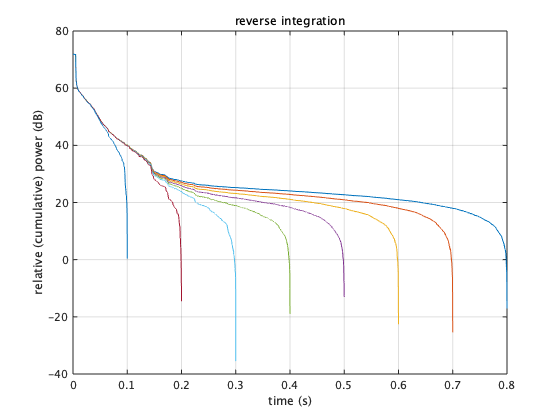

r = extendedResponse;
endPoints = [0.8 0.7 0.6 0.5 0.4 0.3 0.2 0.1];
txExtResp = (1:length(extendedResponse))' / fs;
figure;
for ii = 1:length(endPoints)
    revIntegration = cumsum(r(txExtResp < endPoints(ii)) .^ 2, 'reverse');
    plot(txExtResp(txExtResp < endPoints(ii)), 10 * log10(revIntegration));
    grid on
    hold on
end
title('reverse integration')
xlabel('time (s)')
ylabel('relative (cumulative) power (dB)')

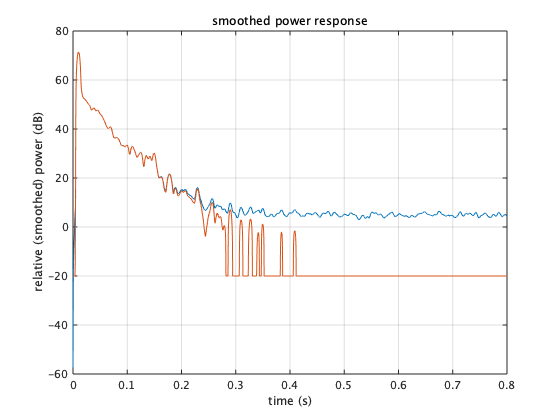


hSmooth = hanning(round(0.01 * fs));
r10ms = fftfilt(hSmooth, r .^ 2);
meanFloor = mean(r10ms(txExtResp > 0.5 & txExtResp < .8));
r10msFix = max(0.01, r10ms - meanFloor * 1.4);
figure;
plot(txExtResp(txExtResp < endPoints(1)), 10 * log10(r10ms(txExtResp < endPoints(1))));
hold all;
plot(txExtResp(txExtResp < endPoints(1)), 10 * log10(r10msFix(txExtResp < endPoints(1))));
grid on;
title('smoothed power response')
xlabel('time (s)')
ylabel('relative (smoothed) power (dB)')

### Linear regression from level to time

t = a r + b + eps

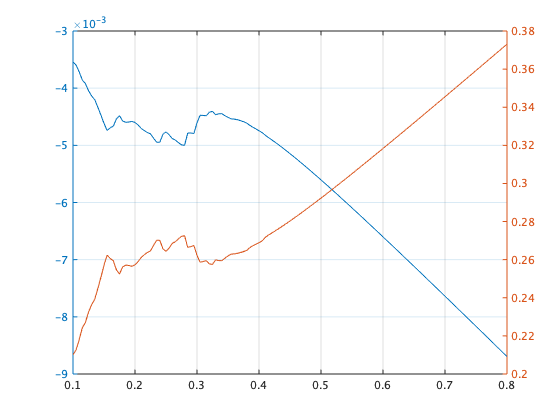

startTime = 0.03; % removing direct response
endPoints = 0.1:0.005:0.8;
ee = zeros(length(endPoints), 1);
aaVe = zeros(length(endPoints), 2);
for ii = 1:length(endPoints)
    y = txExtResp(txExtResp > startTime & txExtResp < endPoints(ii));
    tmpr = 10 * log10(r10msFix(txExtResp > startTime & txExtResp < endPoints(ii)));
    rr = [tmpr ones(length(tmpr), 1)];
    aa = inv(rr' * rr) * (rr' * y);
    aaVe(ii, :) = aa(:)';
    ee(ii) = std(y - rr * aa(:));
end
figure;
yyaxis left
plot(endPoints, aaVe(:, 1)); grid on;
yyaxis right
plot(endPoints, aaVe(:, 2)); grid on;

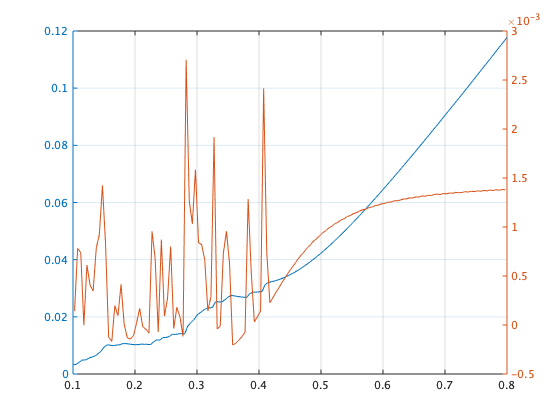


figure;
yyaxis left
plot(endPoints, ee); grid on;
yyaxis right
plot((endPoints(1:end-1) + endPoints(2:end)) / 2, diff(ee));
grid on;

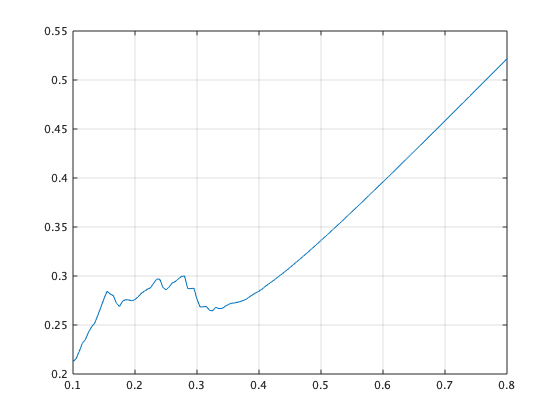


figure;
plot(endPoints, aaVe(:, 1) * (-60)); grid on;

### Frequency dependent reverbation time visualization using reverse integration

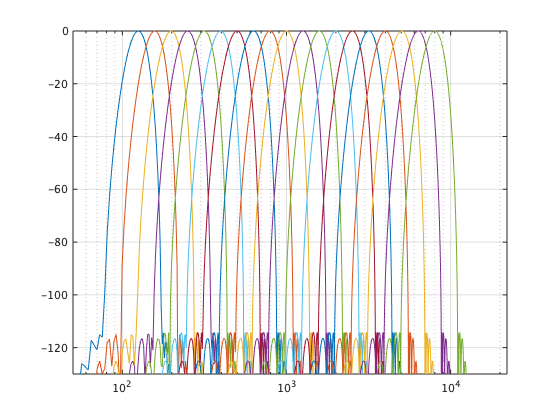

fl = 125;
fh = 8000;
nChannelPerOct = 3;
stretchingFactor = 2.6;
wvltStr = designAnalyticWavelet(fs, fl, fh, nChannelPerOct, stretchingFactor);
fcList = wvltStr.fc_list;
nChannels = length(fcList);
figure;
for ii = 1:nChannels
    semilogx(fxUnitResp, 20*log10(abs(fft(wvltStr.wvlt(ii).w, fftlUnitResp))));
    grid on;
    hold all
end
%set(gca, 'xlim', [50 fs / 2]);
axis([50 fs/2 -130 0])


lLowestWavelet = length(wvltStr.wvlt(1).w);
extendedResponseEx = [extendedResponse(txExtResp < 0.8); zeros(lLowestWavelet, 1)];
lFilteredResponse = length(extendedResponse(txExtResp < 0.8));
waveletOutput = zeros(lFilteredResponse, nChannels);
outIndex = 1:lFilteredResponse;
for ii = 1:nChannels
    tmp = fftfilt(wvltStr.wvlt(ii).w, extendedResponseEx);
    waveletOutput(:, ii) = tmp(wvltStr.wvlt(ii).bias + outIndex);
end

revIntRaw = cumsum(abs(waveletOutput) .^ 2, 'reverse');
reverseIntegrationView = revIntRaw * 0;
refPoint = 500;
for ii = 1:nChannels
    reverseIntegrationView(:, ii) = revIntRaw(:, ii) / revIntRaw(refPoint, ii);
end
reverseIntegrationView = max(0.0001, min(1, reverseIntegrationView));
